# ED and Eo Calcuations for each month

l = 32;
sigma = 30;
sqm = 112.80;
u = 0.24;
y = 45;

adls = [];

disp("ED AND EO MONTH CALCULATOR");

ED AND EO MONTH CALCULATOR


month = input("Please input a month: [1-12] ");
data = SolarChart2(month,:);
delta = data.DeclinatioNdeg;
et = data.EquationOfTimemin;
a = data.A * 3.2;
b = data.B;
c = data.C;
sunrise = data.AvgSunriseAMMT;

ed = dayEDCalc(l, sigma, y, delta, et, a, b, c, sunrise);
eo =u*ed*sqm;

disp(month + " MONTH ED: " + ed)

10 MONTH ED: 6653.0774


disp(month + " MONTH EO: " + eo)

10 MONTH EO: 180112.1114


# Battery Calcuations

v = 5

v = 5

ah = 30 %30

ah = 30


ec = (v*ah)/1000

ec = 0.1500

el = 0.5 * ec

el = 0.0750


els = (36.3 * 0.6)*(1 + (0.5+0.2)/(100))

els = 21.9325

vs = v * els;
ecs = els/v

ecs = 4.3865

ahs = (ecs)/(vs)*1000

ahs = 40


nbs = vs/v

nbs = 21.9325

nbp = ahs/ah

nbp = 1.3333

## Eo Graph

x = linspace(0,1,6);
%y = [oct_eo, nov_eo, dec_eo, jan_eo, feb_eo, mar_eo];
%plot(x,y)
%xlabel('winter months')
%ylabel('eo')
%title('Eo Graph')

## ADL Graph

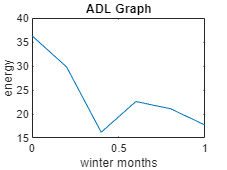

y = [36.3, 29.8, 16.2, 22.6, 21.1, 17.7];
plot(x,y)
xlabel('winter months')
ylabel('energy')
title('ADL Graph')